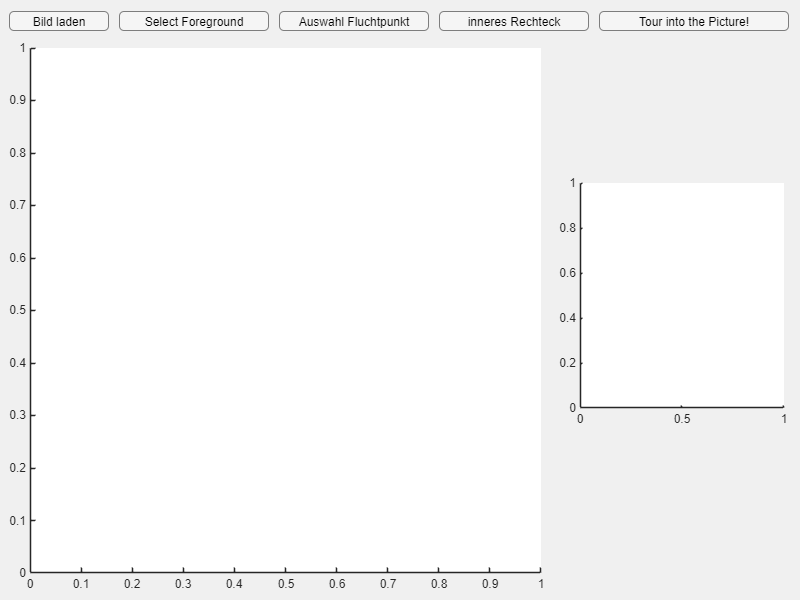

clc;
clearvars;

%------------------------------- Change log --------------------------------------
% 'BackgroundAxes': Background display zone
% 'ForegroundAxes': foreground display zone
% 'Image': Background
% 'ForegroundImage': Foreground objects

tip_gui;

function tip_gui
    % Create a figure for the GUI
    fig = uifigure('Name', 'Tour Into the Picture', 'Position', [100, 100, 800, 600]);

    % Load image button
    uibutton(fig, 'Position', [10, 570, 100, 20], 'Text', 'Bild laden', 'ButtonPushedFcn', @(btn, event) loadImage(fig));
    
    % Extruct foreground objects
    uibutton(fig, 'Position', [120, 570, 150, 20], 'Text', 'Select Foreground', 'ButtonPushedFcn', @(btn, event) selectForeground(fig));
    
    % Select vanishing point button
    uibutton(fig, 'Position', [280, 570, 150, 20], 'Text', 'Auswahl Fluchtpunkt', 'ButtonPushedFcn', @(btn, event) selectVanishingPoint(fig));

    % Draw inner rectangle button
    uibutton(fig, 'Position', [440, 570, 150, 20], 'Text', 'inneres Rechteck', 'ButtonPushedFcn', @(btn, event) drawInnerRectangle(fig));
    
    % Start animation button (bottom right corner)
    uibutton(fig, 'Position', [600, 570, 190, 20], 'Text', 'Tour into the Picture!', 'ButtonPushedFcn', @(btn, event) startAnimation(fig));

    % Axes for displaying the image and animation
    axBackground = uiaxes(fig, 'Position', [10, 10, 540, 550]); % Adjusted size to accommodate the button
    setappdata(fig, 'BackgroundAxes', axBackground);

    % Axes for displaying the foreground image
    axForeground = uiaxes(fig, 'Position', [560, 175, 230, 250]);
    setappdata(fig, 'ForegroundAxes', axForeground);

    % Initialize data
    setappdata(fig, 'Image', []);
    setappdata(fig, 'VanishingPoint', []);
    setappdata(fig, 'InnerRectangle', []);
    setappdata(fig, 'VanishingPointHandle', []); % Store handle for vanishing point
    setappdata(fig, 'MeshLines', []); % Store handles for mesh lines
    setappdata(fig, 'RectangleHandle', []); % Store handle for inner rectangle
end

function loadImage(fig)
    [file, path] = uigetfile({'*.jpg;*.png'}, 'Select an Image');
    if isequal(file, 0)
        return;
    end
    img = imread(fullfile(path, file));
    setappdata(fig, 'Image', img);
    axBackground = getappdata(fig, 'BackgroundAxes');
    imshow(img, 'Parent', axBackground);
    % Adjust the axis properties to fit the image
    axis(axBackground, 'image');
    axBackground.XTick = [];
    axBackground.YTick = [];
end

function selectForeground(fig)
    axBackground = getappdata(fig, 'BackgroundAxes');
    axForeground = getappdata(fig, 'ForegroundAxes');
    img = getappdata(fig, 'Image');
    masks = getappdata(fig, 'Masks');

    if isempty(img)
        uialert(fig, 'Load an image first!', 'Image Not Found');
        return;
    end

    % Initialize with the original image
    compositeBackground = img;
    % Initialize the foreground image as fully transparent (all zeros)
    foregroundImage = zeros(size(img), 'like', img);
    
    finished = false;
    while ~finished
        h = drawpolygon('Parent', axBackground, 'Color', 'b');

        % Wait for user confirmation
        wait(h);
        
        if isvalid(h)
            % Create mask from polygon
            mask = createMask(h, img);
            masks{end+1} = mask;

            % Update composite foreground image
            currentForeground = img;
            currentForeground(repmat(~mask, [1, 1, 3])) = 0;
            foregroundImage = max(foregroundImage, currentForeground);

            % Update background
            for k = 1:3  % Apply regionfill to each channel
                compositeBackground(:,:,k) = regionfill(compositeBackground(:,:,k), mask);
            end

            % Display updated foreground and background
            imshow(foregroundImage, 'Parent', axForeground);
            imshow(compositeBackground, 'Parent', axBackground);
        else
            uialert(fig, 'Polygon was deleted or is invalid.', 'Error');
        end

        % Ask user if they want to add another foreground
        choice = uiconfirm(fig, 'Do you want to add another foreground?', 'Add Foreground', ...
                           'Options', {'Yes', 'No'}, 'DefaultOption', 2, 'CancelOption', 2);
        finished = strcmp(choice, 'No');
    end

    % Store the updated images and masks
    setappdata(fig, 'Image', compositeBackground);
    setappdata(fig, 'Masks', masks);
    setappdata(fig, 'ForegroundImage', foregroundImage);

end